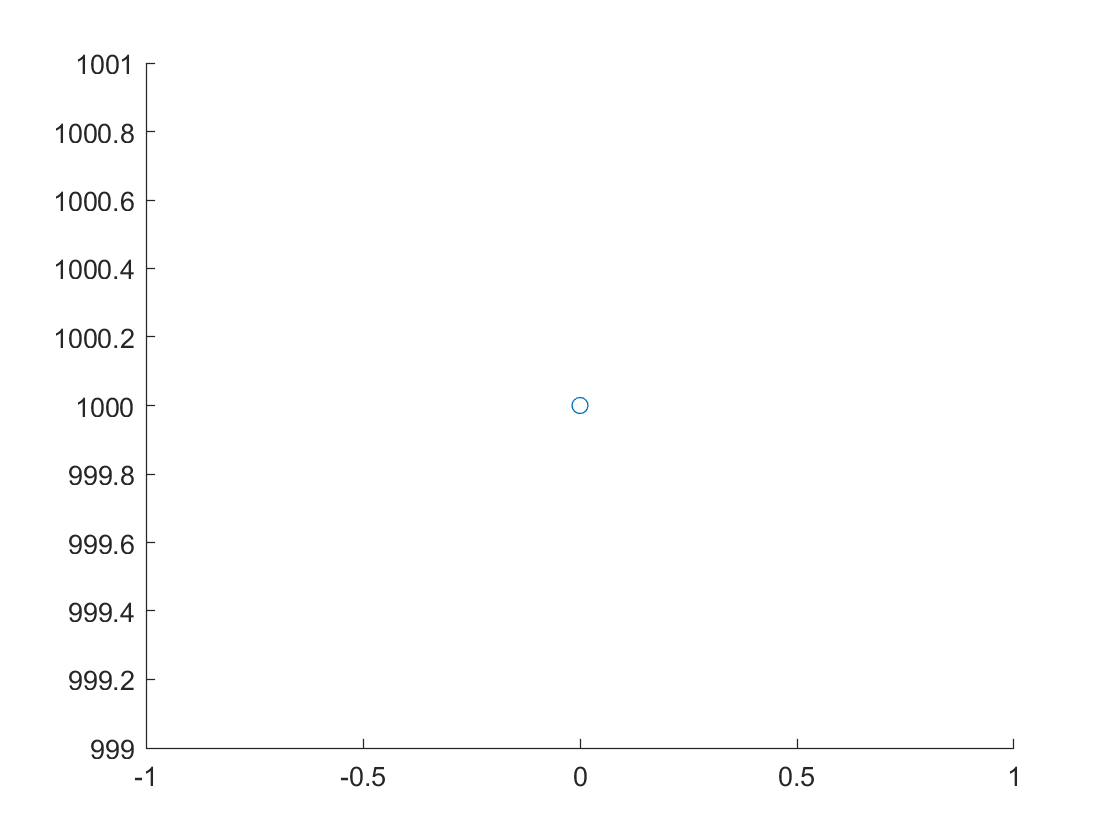

mu = 2;
m = 2000;
l1 = 0.6;
l2 = 0.1;
figure;
a= 0;
b=1000;
c=0.583333333334;
d=1;
hold on
paintii(a,b,c,d,1)
hold off

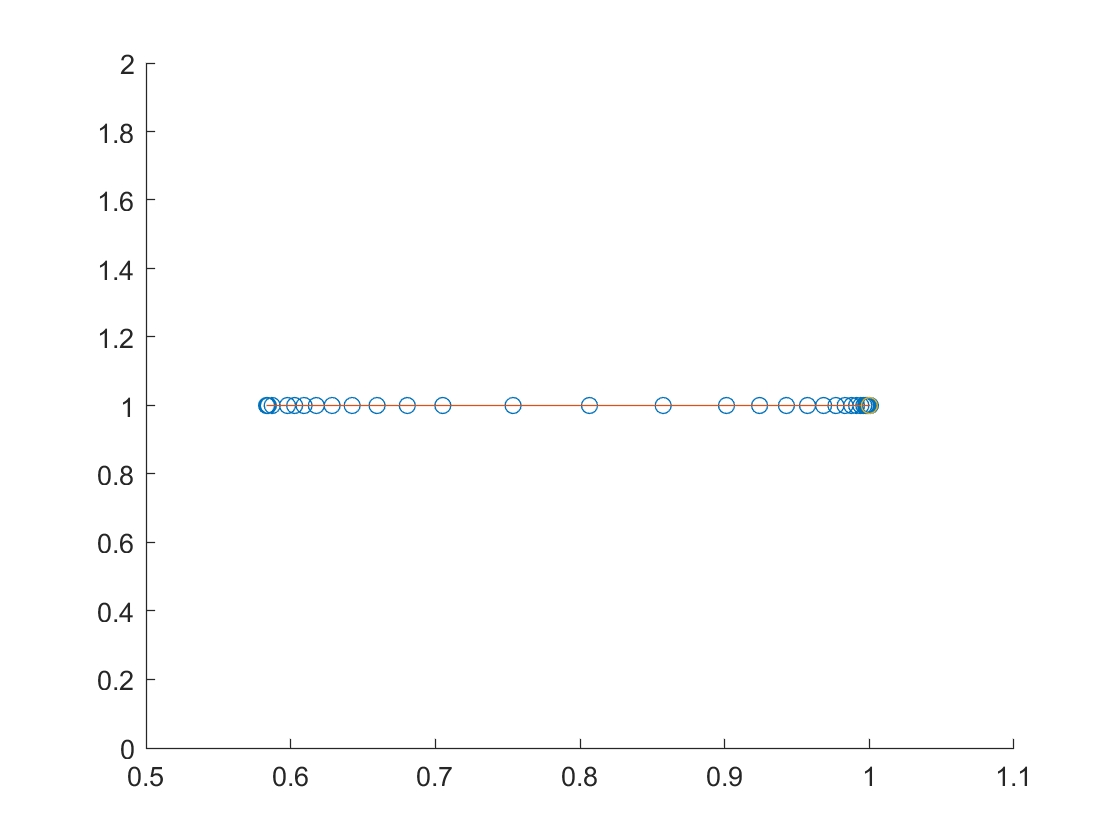

figure;
hold on
paintii(a,b,c,d,2)
scatter(1,1)
hold off

function yp = ll(t,y)
Mu = 2;
m = 2000;
l1 =  0.6;
l2 = 0.1;
a = l1*(2*y(3)-1)*y(1) - l2*y(1) - 1*(2*y(3)-1)*y(1)*y(1)/m - 1*(2*y(4)-1)*y(2)*y(1)/Mu/m;
b = l1*(2*y(4)-1)*y(2) - l2*y(2) - 1*(2*y(4)-1)*y(2)*y(2)/m - 1*(2*y(3)-1)*y(1)*y(2)/m/Mu;
c = l1*(1-y(3))*y(3) + l2*(y(3)-1) + 2*(y(3)-1)*y(1)*y(3)/m + 1*(2*y(3)*y(4)-y(3)-y(4))*y(2)/Mu/m;
d = l1*(1-y(4))*y(4) + l2*(y(4)-1) + 2*(y(4)-1)*y(2)*y(4)/m + 1*(2*y(3)*y(4)-y(3)-y(4))*y(1)/Mu/m;
yp = [a;b;c;d];
if d >0
    d
end
end

function paintii(a,b,c,d,i)
    t0 = 0;
    tfinal = 200;
    y0 = [a;b;c;d];
    [t,y] = ode45(@ll,[t0 tfinal],y0);
        if i == 1
            scatter(y(:,1),y(:,2))
        end
        if i == 2
            scatter(y(:,3),y(:,4))
            plot(y(:,3),y(:,4))
        end

end